Load the data from runs 1-4 in MATLAB. The trigger (channel 18) marks second 2 of each trial.

Information about the cue direction in each run and trial is in .mat files on Courseworks in the

Experiment Files/Lab 9/Homework folder. Using this information, separate the trials into two groups:

left (row 1) and right (row 2). There should be 80 left and 80 right. (1 pt)

%get rid of the existing data that we have. 

clear; close all; clc;

run1_file = 'MotorImageryCSP_Data_Run1b_18_11_2025_11_54_09_0000.mat';
run3_file = 'MotorImageryCSP_Data_Run3_18_11_2025_12_29_07_0000.mat';
run4_file = 'MotorImageryCSP_Data_Run4_18_11_2025_12_38_31_0000.mat';

%we failed to set the file size to 100MB for run2, meaning that we have to
%concatinate them here 
run2_pattern = 'MotorImageryCSP_Data_Run2_18_11_2025_12_18_09_*.mat';

% and then these are all of the files that contain the left v right
% information
cue_files = {
    'Homework/classrun1.mat';
    'Homework/classrun2.mat';
    'Homework/classrun3.mat';
    'Homework/classrun4.mat';
};

%load the 1st run
S1 = load(run1_file);
Y1 = S1.y;
fs1 = S1.SR;
trig1 = Y1(18,:);
t1 = (0:length(trig1)-1)/fs1;

%2nd run with the concatination
files2 = dir(run2_pattern);

Y2_all = [];
trigger2_all = [];

for k = 1:length(files2)
    S2 = load(files2(k).name);
    if k == 1
        fs2 = S2.SR;
    end
    Y2_all      = [Y2_all      S2.y];
    trigger2_all = [trigger2_all S2.y(18,:)];
end

Y2 = Y2_all;
trig2 = trigger2_all;
t2 = (0:length(trig2)-1)/fs2;

%run3
S3 = load(run3_file);
Y3 = S3.y;
fs3 = S3.SR;
trig3 = Y3(18,:);
t3 = (0:length(trig3)-1)/fs3;

%run4
S4 = load(run4_file);
Y4 = S4.y;
fs4 = S4.SR;
trig4 = Y4(18,:);
t4 = (0:length(trig4)-1)/fs4;

%now lets make sure to pack everything into arrays for looping. 
all_Y    = {Y1, Y2, Y3, Y4};
all_fs   = {fs1, fs2, fs3, fs4};
all_trig = {trig1, trig2, trig3, trig4};
all_t    = {t1, t2, t3, t4};

%these are going to be the output structures that we have. 
all_left = {};
all_right = {};
left_count = 0;
right_count = 0;

%process all 4 of the runs 
for R = 1:4

    Y    = all_Y{R};
    fs   = all_fs{R};
    trig = all_trig{R};

    % took me a while but we have to
    % find the trigger from the rising edges (with the arrow onset = second 2)
    d = diff(trig);
    rising_idx = find(d > 0) + 1;
    rising_times = rising_idx / fs;

    %so that means that the trial onset bascially equals the trigger time -
    %2s
    trial_starts = rising_times - 2;

    % then we want to make sure that we are loading the correct cue variable name (z1, z2, z3, or z4)
    C = load(cue_files{R});
    varname = sprintf('z%d', R); %"z1", "z2", "z3", or "z4"
    z = C.(varname); 

    % assign trials for left or right
    for j = 1:40

        if z(1,j) == 1
            left_count = left_count + 1;
            all_left{left_count} = struct( ...
                'run', R, ...
                'trial', j, ...
                'start_time', trial_starts(j));
        else
            right_count = right_count + 1;
            all_right{right_count} = struct( ...
                'run', R, ...
                'trial', j, ...
                'start_time', trial_starts(j));
        end
    end
end

%then just disp the final counts we get. 
disp(['LEFT trials:  ' num2str(left_count)]);

LEFT trials:  80


disp(['RIGHT trials: ' num2str(right_count)]);

RIGHT trials: 80


Filter your data from 8-20Hz and find the average power of each electrode during left versus right

imagined movements. Use the time interval when the subject is actively imagining movement (4.5s

to 8s after trial onset). Can you see a clear difference between the two? (6 pts)

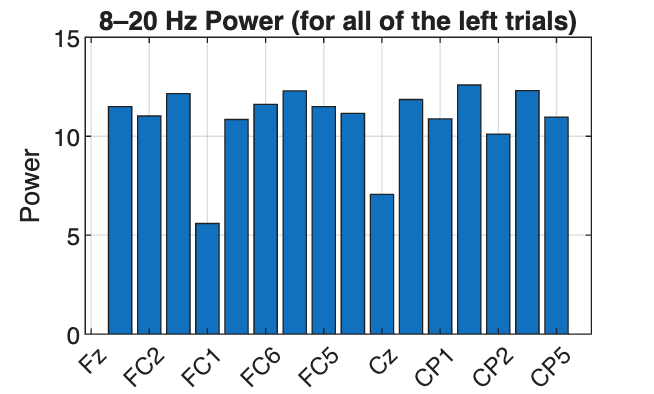

clearvars -except all_left all_right all_Y all_fs all_trig all_t;
%make seperate cell

%% all of the electrode names we used. All 16 
electrodes = {'Fz','FC2','FC1','FC6','FC5','Cz','CP1','CP2','CP5','CP6',...
              'Pz','P4','P3','PO8','PO7','Oz'};

electrode_idx = 2:17;
fs_main = 256;

%% Using the butterworth 8–20hz bandpass filter
[b,a] = butter(4, [8 20] / (fs_main/2), 'bandpass');

% then just make this a helper so that we can compute power for the one trial
compute_power_for_trial = @(Y, fs, start_time) ...
    mean( ...
        ( ...
            filtfilt(b, a, ...
                double( ...
                    Y(electrode_idx, ...
                      round((start_time + 4.5) * fs) : ...
                      round((start_time + 8.0) * fs) ...
                    )' ...
                ) ...
            )' ...
        ).^2 ...
    , 2)';


%this is going to be for the left trials 

power_left = zeros(80, 16);

for n = 1:80
    R  = all_left{n}.run;
    ts = all_left{n}.start_time;
    fs = all_fs{R};
    Y  = all_Y{R};

    power_left(n,:) = compute_power_for_trial(Y, fs, ts);
end

power_left_avg = mean(power_left, 1);


%and the right

power_right = zeros(80, 16);

for n = 1:80
    R  = all_right{n}.run;
    ts = all_right{n}.start_time;
    fs = all_fs{R};
    Y  = all_Y{R};

    power_right(n,:) = compute_power_for_trial(Y, fs, ts);
end

power_right_avg = mean(power_right, 1);


%then this will find the difference between left - right. 

power_diff = power_left_avg - power_right_avg;


%plots to visualize. 
%plot left trial power
figure('Color','w');
bar(power_left_avg);
xticklabels(electrodes);
xtickangle(45);
ylabel('Power');
title('8–20 Hz Power (for all of the left trials)');
grid on;

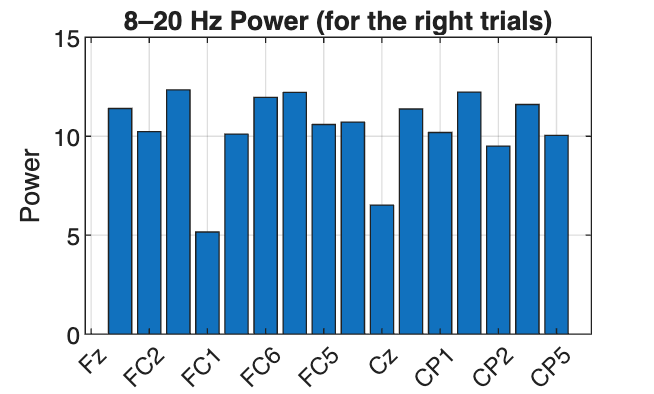


%Right trial power
figure('Color','w');
bar(power_right_avg);
xticklabels(electrodes);
xtickangle(45);
ylabel('Power');
title('8–20 Hz Power (for the right trials)');
grid on;

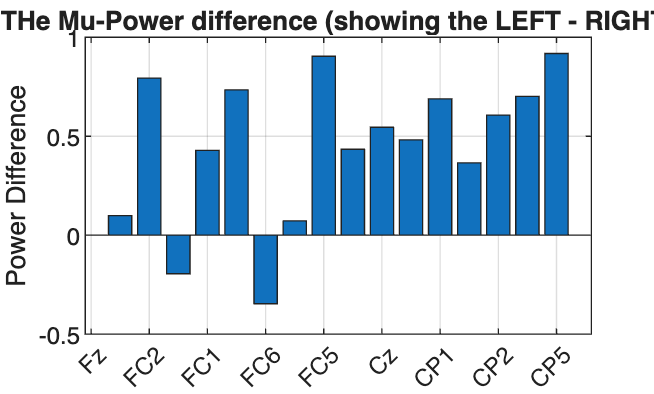


%Left - Right
figure('Color','w');
bar(power_diff);
xticklabels(electrodes);
xtickangle(45);
ylabel('Power Difference');
title('THe Mu-Power difference (showing the LEFT - RIGHT)');
grid on;


%sanity / debug
disp('Average Power LEFT');

Average Power LEFT


disp(power_left_avg);

   11.4986   11.0234   12.1482    5.5899   10.8430   11.6122   12.2915   11.4975   11.1503    7.0617   11.8558   10.8782   12.5901   10.1053   12.3053   10.9615




disp('Average Power RIGHT');

Average Power RIGHT


disp(power_right_avg);

   11.3999   10.2302   12.3431    5.1618   10.1090   11.9589   12.2195   10.5936   10.7161    6.5166   11.3743   10.1897   12.2246    9.4989   11.6042   10.0434




disp('Difference (L - R)');

Difference (L - R)


disp(power_diff);

    0.0987    0.7932   -0.1949    0.4281    0.7340   -0.3468    0.0720    0.9039    0.4342    0.5451    0.4815    0.6885    0.3655    0.6064    0.7012    0.9181



I believe that the mu-band analysis reveals what I would consider to be a noticeable difference between left and right-hand motor imagery. It appears that the right-hand trials are showing a consistent drop in the 8–20 Hz power across several of the right and hemisphere electrodes (including FC6, CP6, and P4), which would then be somewhat indicative of some sort of strong mu-rhythm suppression that was taking place during the right-hand imagination by our subject. It then follows that this would end up creating a clear and lateralized pattern that would be visible on the right side of the scalp. In contrast, we can see that the left-hand imagery does not come together to produce an equally clean effect on the left hemisphere (since we can observe that some of the electrodes, like FC5, CP5, and P3, show weaker or less stable reductions in their respective powers. In my research for this homework, it seems that this asymmetry is typical in these sorts of motor-imagery tasks, where one hand (often the dominant one, which in this case was true) generates stronger and also more reliable neural engagement. Overall, it appears that the data demonstrate a clear separability between our conditions, with the right-hand imagery seeming to produce the more robust and the more spatially coherent suppression pattern.

Calculate the difference between the two conditions for all electrodes and display the subtraction on

the scalp map. You can find the new electrode configuration file ‘CSP.locs’ in Courseworks. In which

parts of the brain do you observe a bigger difference? (3 pts)

%you have to run both of these, should work if you run the notebook all in
%one go
addpath('/Users/alexanderspeer/Desktop/BCI lab/eeglab14_1_2b');  % i guess adjust if needed
eeglab;  %topoplot

eeglab: options file is ~/eeg_options.m
EEGLAB: error while adding plugin "eegplugin_dipfit"
   Error using uimenu
First argument must be a valid parent, such as a Figure or Panel object.
EEGLAB: error while adding plugin "eegplugin_firfilt"
   Error using uimenu
First argument must be a valid parent, such as a Figure or Panel object.


electrodes = {'Fz','FC2','FC1','FC6','FC5','Cz','CP1','CP2','CP5','CP6',...
              'Pz','P4','P3','PO8','PO7','Oz'};

%load the channel locations, nothing to change since using all of the them
locs_path = 'BCI.locs';  %from the courseworks 
chanlocs_full = readlocs(locs_path);

readlocs(): 'loc' format assumed from file extension



% match to them by labell
loc_labels = {chanlocs_full.labels};
[tf, selLocIdx] = ismember(electrodes, loc_labels);

if any(~tf)
    missing = electrodes(~tf);
    error('not found in BCI.locs: %s', strjoin(missing, ', '));
end

chanlocs = chanlocs_full(selLocIdx);

% scalp map
vals = power_diff;  % same thing as before left - right, with the length 16

figure('Color','w');
topoplot(vals, chanlocs, ...
    'electrodes','on', ...
    'numcontour', 6, ...
    'style','map' ...
);

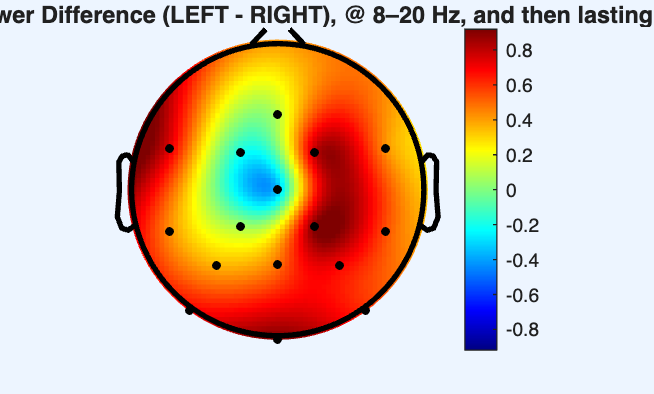


colorbar;
title('the Mu-band Power Difference (LEFT - RIGHT), @ 8–20 Hz, and then lasting 4.5–8 s');

%trying symmetric colors 
mx = max(abs(vals));
caxis([-mx mx]);

It seems to me that (similar to our earlier findings) the scalp map shows that the biggest difference between imagining left and right hand movement appears over the left side of the brain, near the top of the head, which, as we discussed previously, is where the brain controls movements of the right hand. On this topoplot, this area is shown in dark blue on the map, which would then mean that the right-hand imagery ended up causing a noticeably stronger drop in the mu-band power than in the left-hand imagery. 

Once again, this fits what we have come to expect biologically. When someone imagines moving their right hand, it is going to be the left sensorimotor cortex that ends up becoming more active and, as well as having its rhythmic activity decrease. Overall, it appears that the most meaningful and also the most clearly defined difference is located over the left sensorimotor region, which lines up with how the brain would normally go about organizing such hand movement control.

All in all, the results strongly suggest that the subject is just better at visualizing this right-hand movement. To this end, we can see that the right-hand imagery managed to produce clearer and stronger suppression of mu-band activity over the left sensorimotor cortex, which is exactly where we would expect the brain to activate when imagining movements of the right hand. In contrast, the responses to left-hand imagery were weaker and less focused. I would say that this asymmetry makes even more sense given that the subject is both right-handed and also plays violin at Juilliard, meaning that their right hand is likely far more trained, more coordinated, and overly represented more dominantly in the brain. 